%=========================================================================
% Lecture 16: In Class Tutorial
%
% This function calculates the radial equilibrium function for an axially 
% stretched and pressurized thick wall vessel and is part of the set of 
% equations you will implement for your vasculature project
%
% Input data: 
%   luminal pressure (Pi), axial stretch (lambdaz_v) 
%   material parameters, radii in ktf (Ri, Ro)
%
% Output data:
%   approximation of the outer radius, ro
%
% The inverse solution of the radial equilibrium involves finding
% the root of the equation:
%   Pi - int_{ri}^{ro} (tqq-trr)/r dr = 0
%=========================================================================

% Clean environemnts
close all, clear all, clc

Load and Define INPUT DATA


% Control refers to a age-matched healthy model
control_data = load("Input_HypertensionControl_ATA.mat");
test_data = load("Input_Hypertension_ATA.mat");

% Obtains material parameters
material_control = control_data.estimated_parameters;
material_test = test_data.estimated_parameters;

% Loads control parameters
control_lambdaz_exp = control_data.data_kl.lambdaz_exp;
control_Psys_exp = control_data.data_kl.Psys_exp*0.133322; % From mmHg to kPa
control_ref_outer_radius = control_data.data_ktf.or_exp;
control_ref_inner_radius = control_data.data_ktf.ir_exp;
control_thickness = control_data.data_ktf.h_exp;

% Load test parameters (hypertensions)
test_lambdaz_exp = test_data.data_kl.lambdaz_exp;
test_Psys_exp = test_data.data_kl.Psys_exp*0.133322; % From mmHg to kPa
test_ref_outer_radius = test_data.data_ktf.or_exp;
test_ref_inner_radius = test_data.data_ktf.ir_exp;
test_thickness = test_data.data_ktf.h_exp;

%% Solve the equilibrium equation
% Equilibrium equation for a pressurized and axially stretched vessel
% Unknown: outer radius, ro
% ro will be estimated as the roots of the equilibrium equation

H=cell(1,2);
H{1,1}=@equilibrium_r_or_loaded; %handle to equilibrium equation 
H{1,2}=@equilibrum_z_fz_loaded;

% Parameter to be estimated in loaded configuration is the outer radius (ro) 
% x0 is the initial guess for ro based on the input experimental data

       

        
% DELIVERABLE - Plot Luminal Pressure vs Outer Diameter

% All luminal presure to be tested
luminalP = 10:5:140;

% Stretches to be modeled
control_axialStretch = [control_lambdaz_exp, control_lambdaz_exp*1.05, control_lambdaz_exp*0.95];
test_axialStretch = [test_lambdaz_exp, test_lambdaz_exp*1.05, test_lambdaz_exp*0.95];

% Initialize radius result
control_or_est = zeros(3, length(luminalP));
test_or_est = zeros(3, length(luminalP));

% Initialize force results
control_fz_est = zeros(3, length(luminalP));
test_fz_est = zeros(3, length(luminalP));


% Loop through stretches
for stretch_index = 1:length(control_axialStretch)
    control_stretch = control_axialStretch(stretch_index)
    test_stretch = test_axialStretch(stretch_index)
    
    % Loop through pressures

    for P_index = 1:length(luminalP)

        % Current pressure being tested
        Pi = luminalP(P_index);
        Pi = Pi*0.133322; % From mmHg to kPa

        % GET R USING NEWTON RAPHSON% 

        % Control
        control_r = Newton_Raphson(H{1,1}, control_ref_inner_radius, ...
            control_ref_outer_radius, control_stretch, Pi, material_control, ...
            control_ref_outer_radius); 
        % Save results
        control_or_est(stretch_index, P_index) = control_r;

        % Test
        test_r = Newton_Raphson(H{1,1}, test_ref_inner_radius, ...
            test_ref_outer_radius, test_stretch, Pi, material_test, ...
            test_ref_outer_radius); 
        % Save results
        test_or_est(stretch_index, P_index) = test_r;


        % GET CURRENT F WITH OPTIMIZED R

        % Control
        control_fz_est(stretch_index, P_index) = equilibrium_z_fz_loaded(control_ref_inner_radius, ...
            control_ref_outer_radius, control_stretch,material_control,control_r);

        % Test
        test_fz_est(stretch_index, P_index) = equilibrium_z_fz_loaded(test_ref_inner_radius, ...
            test_ref_outer_radius, test_stretch, material_test,test_r);
        
        
    end

end

control_stretch = 1.9761

test_stretch = 1.4955

---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


control_stretch = 2.0749

test_stretch = 1.5703

---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


control_stretch = 1.8773

test_stretch = 1.4207

---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


---
Maximum number of iterations reached
---


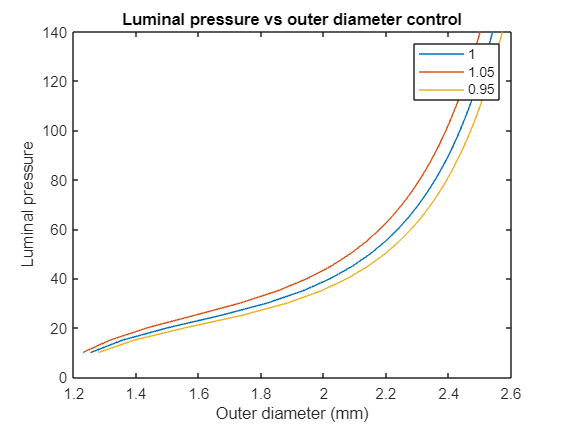

% Find diameter
control_diam = control_or_est .* 2;
test_diam = test_or_est .* 2;

% Plot
figure()
plot(control_diam(1,:),luminalP, control_diam(2,:),luminalP, control_diam(3,:),luminalP)
xlabel("Outer diameter (mm)")
ylabel("Luminal pressure")
legend("1", "1.05", "0.95")
title("Luminal pressure vs outer diameter control")

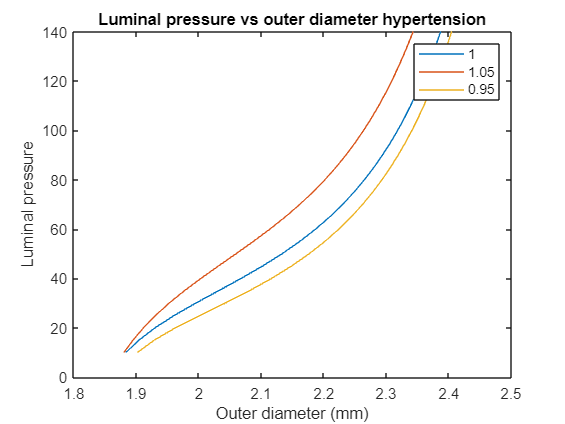


% Plot
figure()
plot(test_diam(1,:),luminalP, test_diam(2,:),luminalP, test_diam(3,:),luminalP)
xlabel("Outer diameter (mm)")
ylabel("Luminal pressure")
legend("1", "1.05", "0.95")
title("Luminal pressure vs outer diameter hypertension")

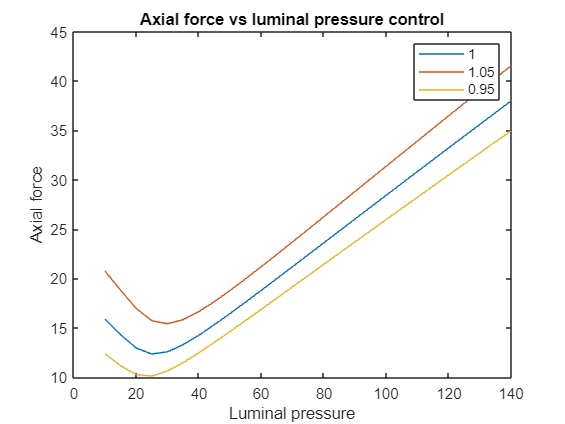


% Plot
figure()
plot(luminalP, control_fz_est(1,:),luminalP, control_fz_est(2,:),luminalP, control_fz_est(3,:))
xlabel("Luminal pressure")
ylabel("Axial force")
legend("1", "1.05", "0.95")
title("Axial force vs luminal pressure control")

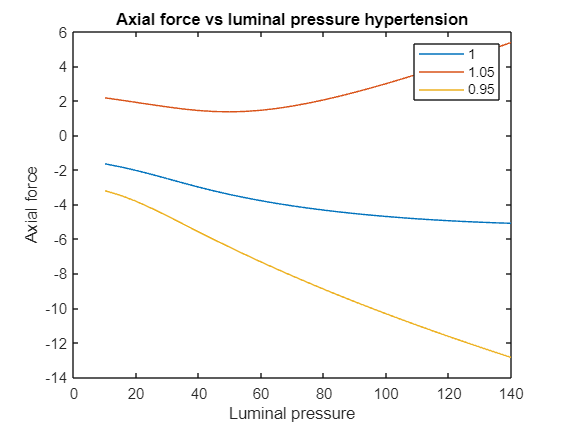


% Plot
figure()
plot(luminalP, test_fz_est(1,:),luminalP, test_fz_est(2,:),luminalP, test_fz_est(3,:))
xlabel("Luminal pressure")
ylabel("Axial force")
legend("1", "1.05", "0.95")
title("Axial force vs luminal pressure hypertension")

% DELIVERABLE plot radial, circumferential, axial components of Cauchy Stress vs radial position

R_control = linspace(control_ref_inner_radius,control_ref_outer_radius,20)

R_control =     0.4998    0.5065    0.5131    0.5197    0.5263    0.5330    0.5396    0.5462    0.5529    0.5595    0.5661    0.5728    0.5794    0.5860    0.5926    0.5993    0.6059    0.6125    0.6192    0.6258


R_test = linspace(test_ref_inner_radius,test_ref_outer_radius,20)

R_test =     0.6339    0.6466    0.6592    0.6719    0.6845    0.6972    0.7098    0.7224    0.7351    0.7477    0.7604    0.7730    0.7856    0.7983    0.8109    0.8236    0.8362    0.8489    0.8615    0.8741



% control
[control_stress_rr control_stress_theta control_stress_zz] = lagrange_stress(control_ref_inner_radius,control_ref_outer_radius,control_axialStretch(1,1),control_Psys_exp,material_control,control_ref_outer_radius)

control_stress_rr =     2.4403    2.7618    3.0978    3.4486    3.8147    4.1963    4.5939    5.0080    5.4390    5.8873    6.3535    6.8381    7.3417    7.8649    8.4083    8.9725    9.5583   10.1664   10.7977   11.4529


control_stress_theta =  -388.1349 -391.8767 -395.3829 -398.6707 -401.7559 -404.6527 -407.3742 -409.9320 -412.3371 -414.5993 -416.7275 -418.7300 -420.6144 -422.3876 -424.0561 -425.6257 -427.1020 -428.4899 -429.7942 -431.0192


control_stress_zz =  -457.4304 -456.8356 -456.2154 -455.5690 -454.8952 -454.1932 -453.4616 -452.6994 -451.9052 -451.0777 -450.2153 -449.3165 -448.3795 -447.4026 -446.3836 -445.3206 -444.2111 -443.0527 -441.8426 -440.5778



% test
[test_stress_rr test_stress_theta test_stress_zz] = lagrange_stress(test_ref_inner_radius,test_ref_outer_radius,test_axialStretch(1,1),test_Psys_exp,material_test,test_ref_outer_radius)

test_stress_rr =         6704       13392       20208       27360       35040       43488       52992       63936       76928       92800      112640      138368      173056      221696      292864      403456      585728      909312     1540096     2883584


test_stress_theta = 1.0e+20 *

   -0.0011   -0.0011   -0.0012   -0.0013   -0.0015   -0.0018   -0.0022   -0.0028   -0.0036   -0.0050   -0.0071   -0.0106   -0.0167   -0.0279   -0.0497   -0.0948   -0.1962   -0.4446   -1.1189   -3.1793


test_stress_zz = 1.0e+20 *

   -0.0011   -0.0011   -0.0012   -0.0013   -0.0015   -0.0018   -0.0022   -0.0028   -0.0036   -0.0050   -0.0071   -0.0106   -0.0167   -0.0279   -0.0497   -0.0948   -0.1962   -0.4446   -1.1189   -3.1793


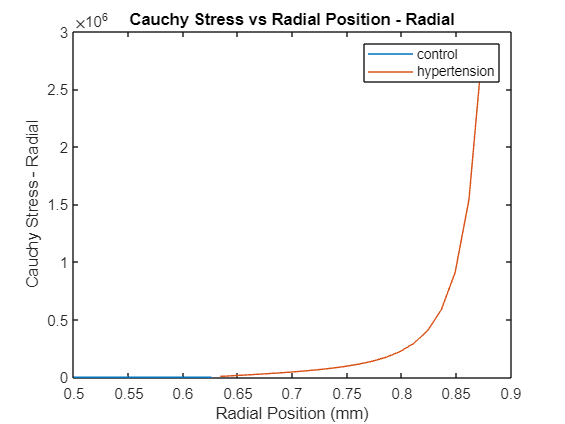

        
figure()
plot(R_control, control_stress_rr,R_test,test_stress_rr)
xlabel('Radial Position (mm)')
ylabel('Cauchy Stress - Radial')
legend('control','hypertension')
title('Cauchy Stress vs Radial Position - Radial')

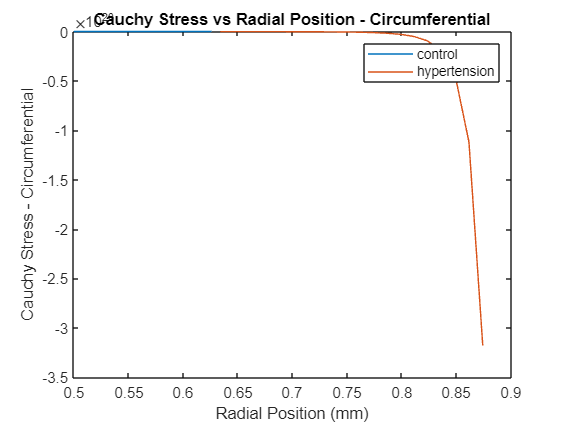


figure()
plot(R_control, control_stress_theta,R_test,test_stress_theta)
xlabel('Radial Position (mm)')
ylabel('Cauchy Stress - Circumferential')
legend('control','hypertension')
title('Cauchy Stress vs Radial Position - Circumferential')

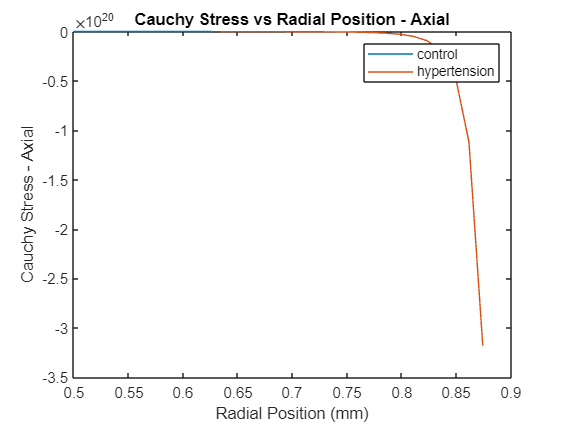


figure()
plot(R_control, control_stress_zz,R_test,test_stress_zz)
xlabel('Radial Position (mm)')
ylabel('Cauchy Stress - Axial')
legend('control','hypertension')
title('Cauchy Stress vs Radial Position - Axial')